# No current


Starting wave glider path planning...
Maximum iterations reached. Goal may not be reachable with wave glider constraints.
Wave Glider Path Stats:
  Path length: 119.17 m
  Total time: 372.6 s
  Average ground speed: 0.32 m/s
  Waypoints: 1863
  Total turning: 39.46 rad (2260.65 deg)

--- Computation Performance ---
Total computation time: 0.2272 seconds

--- Wave Glider Parameters ---
Average Speed: 0.32 m/s
Turning Radius: 0.98 m
Max Turn Rate: 0.327 rad/s (18.7 deg/s)


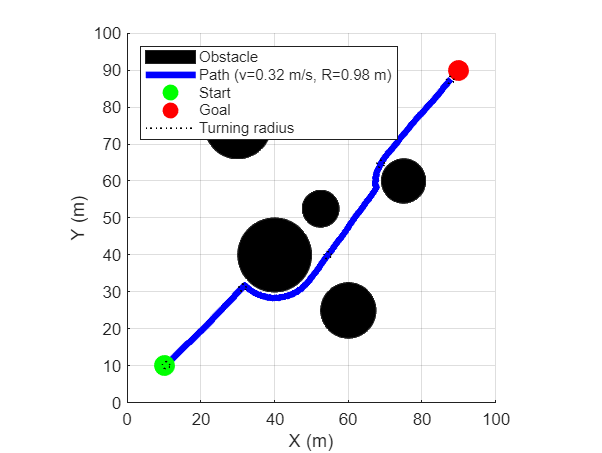

function apf_path_planning_wave_glider()
    % Artificial Potential Field Method for Local Path Planning
    % With Wave Glider Dynamics
    % No currrent, multiple static obstalces example

    % Clear workspace
    clear; close all; clc;

    % Environment setup - 100x100m
    field_size = 100;     % Size of the field
    resolution = 0.5;     % Grid resolution
    x = 0:resolution:field_size;
    y = 0:resolution:field_size;
    [X, Y] = meshgrid(x, y);

    % Robot parameters
    start_pos   = [10, 10];      % Starting position
    goal_pos    = [90, 90];      % Goal position
    robot_radius = 1.53;          % Robot radius for collision detection

    % WAVE GLIDER DYNAMICS PARAMETERS
    wave_glider.avg_speed = 0.32;        % Average speed (m/s)
    wave_glider.turning_radius = 0.98;   % Minimum turning radius (m)
    wave_glider.max_turn_rate = wave_glider.avg_speed / wave_glider.turning_radius; % rad/s

    % Obstacles (circles defined by [x_center, y_center, radius])
    obstacles = [
        40, 40, 10;
        60, 25, 7.5;
        30, 75, 9;
        75, 60, 6;
        52.5, 52.5, 5
    ];

    % APF parameters
    k_att = 0.5;        % Attractive force gain
    k_rep = 15;       % Repulsive force gain
    d0    = 20;       % Influence distance of obstacles
    dt    = 0.2;        % Time step for wave glider dynamics (s)
    max_iterations = 10000;

    % Calculate potentials
    U_att   = attractive_potential(X, Y, goal_pos, k_att);
    U_rep   = repulsive_potential(X, Y, obstacles, k_rep, d0);
    U_total = U_att + U_rep;

    % Path planning with wave glider dynamics
    tic;
    
    path_with_dynamics = path_planning_wave_glider(start_pos, goal_pos, obstacles, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, wave_glider);
    
    computation_time = toc;
    fprintf('\n--- Computation Performance ---\n');
    fprintf('Total computation time: %.4f seconds\n', computation_time);

    % Display wave glider parameters
    fprintf('\n--- Wave Glider Parameters ---\n');
    fprintf('Average Speed: %.2f m/s\n', wave_glider.avg_speed);
    fprintf('Turning Radius: %.2f m\n', wave_glider.turning_radius);
    fprintf('Max Turn Rate: %.3f rad/s (%.1f deg/s)\n', wave_glider.max_turn_rate, rad2deg(wave_glider.max_turn_rate));

    % Visualization
    visualize_results(X, Y, U_total, start_pos, goal_pos, ...
        obstacles, path_with_dynamics, field_size, wave_glider);
end

%% Wave Glider Path Planning
function path = path_planning_wave_glider(start_pos, goal_pos, obstacles, ...
    k_att, k_rep, d0, dt, max_iter, robot_radius, wave_glider)

    % Local-minima escape parameters
    stagnation_window     = 70;      % steps to look back for progress
    min_improve           = 0.5;     % m of improvement required over the window
    force_eps             = 0.05;    % N-ish threshold: "gradient nearly zero"
    escape_angle_deg      = 85;      % rotate APF force by this angle during escape
    escape_duration_sec   = 1;       % seconds to keep escaping
    escape_steps_default  = max(1, round(escape_duration_sec / dt));

    % State
    current_pos     = start_pos;
    current_heading = 0;                         % rad
    current_speed   = wave_glider.avg_speed;     % m/s
    goal_threshold  = 1;                       % m

    path     = current_pos;
    headings = current_heading;

    % Progress tracking
    dist_hist = [];
    best_dist_recent = inf;
    no_improve_steps = 0;

    % Escape mode state
    escape_steps_left = 0;
    escape_sign       = 1;  % +1 or -1
    escape_angle_rad  = deg2rad(escape_angle_deg);

    fprintf('\nStarting wave glider path planning...\n');
    
    for iter = 1:max_iter
        % Compute APF force at the current position
        [Fx, Fy] = calculate_forces(current_pos, goal_pos, obstacles, ...
                                    k_att, k_rep, d0);

        % Local-minima prevention: decide if should enter escape mode
        dist_to_goal = norm(current_pos - goal_pos);

        % Track recent progress
        dist_hist = [dist_hist; dist_to_goal]; %#ok<AGROW>
        if numel(dist_hist) > stagnation_window
            recent = dist_hist(end-stagnation_window+1:end);
            best_recent = min(recent);
            % If not clearly beating the recent best OR the force is tiny, consider "stuck"
            if (best_dist_recent - dist_to_goal) < min_improve
                no_improve_steps = no_improve_steps + 1;
            else
                no_improve_steps = 0;
            end
            best_dist_recent = min(best_dist_recent, dist_to_goal);

            if (no_improve_steps >= stagnation_window) || (hypot(Fx, Fy) < force_eps)
                % Start/refresh a short escape where bias the force sideways
                escape_sign       = sign(randn); % random left/right
                if escape_sign == 0, escape_sign = 1; end
                escape_steps_left = escape_steps_default;
                no_improve_steps  = 0;  % reset the counter
            end
        else
            % Initialise the reference as the best seen so far
            best_dist_recent = min(best_dist_recent, dist_to_goal);
        end

        % If escaping, rotate the APF force by escape_angle
        if escape_steps_left > 0
            [Fx, Fy] = rotate_vec(Fx, Fy, escape_sign * escape_angle_rad);
            escape_steps_left = escape_steps_left - 1;
        end

        % Desired heading from (possibly rotated) force
        desired_heading = atan2(Fy, Fx);
        
        % Calculate heading error and apply turning radius constraint
        heading_error = angle_diff(desired_heading, current_heading);
        
        % Limit turn rate based on turning radius
        max_heading_change = wave_glider.max_turn_rate * dt;
        
        if abs(heading_error) > max_heading_change
            % Can't turn fast enough - limit the turn
            heading_change = sign(heading_error) * max_heading_change;
            current_heading = current_heading + heading_change;
        else
            % Can achieve desired heading
            current_heading = desired_heading;
        end
        
        % Normalize heading to [-pi, pi]
        current_heading = atan2(sin(current_heading), cos(current_heading));
        
        % Calculate velocity vector
        vx = current_speed * cos(current_heading);
        vy = current_speed * sin(current_heading);
        
        % Update position
        next_pos = current_pos + dt * [vx, vy];

        % Collision check
        collision = false;
        for i = 1:size(obstacles, 1)
            oc = obstacles(i, 1:2); orad = obstacles(i, 3);
            if norm(next_pos - oc) < (orad + robot_radius)
                collision = true; 
                break;
            end
        end

        if ~collision
            current_pos = next_pos;
            path = [path; current_pos]; %#ok<AGROW>
            headings = [headings; current_heading]; %#ok<AGROW>
        else
            
            % Try turning left or right to avoid collision
            for turn_sign = [-1, 1] % Try left turn first, then right
                test_heading = current_heading + turn_sign * max_heading_change;
                test_vx = current_speed * cos(test_heading);
                test_vy = current_speed * sin(test_heading);
                test_pos = current_pos + dt * [test_vx, test_vy];
                
                % Check if this avoids collision
                test_collision = false;
                for i = 1:size(obstacles, 1)
                    oc = obstacles(i, 1:2); orad = obstacles(i, 3);
                    if norm(test_pos - oc) < (orad + robot_radius)
                        test_collision = true;
                        break;
                    end
                end
                
                if ~test_collision
                    current_heading = test_heading;
                    current_pos = test_pos;
                    path = [path; current_pos]; %#ok<AGROW>
                    headings = [headings; current_heading]; %#ok<AGROW>
                    break;
                end
            end
            
            % If collided, also nudge escape mode so don't get re-trapped
            if collision
                escape_sign       = sign(randn); 
                if escape_sign == 0, escape_sign = 1; end
                escape_steps_left = escape_steps_default;
            end
        end

        % Goal check
        if norm(current_pos - goal_pos) < goal_threshold
            fprintf('Goal reached in %d iterations with wave glider dynamics.\n', iter);
            break;
        end

    end

    if iter == max_iter
        fprintf('Maximum iterations reached. Goal may not be reachable with wave glider constraints.\n');
    end

    % Path statistics
    if size(path, 1) > 1
        path_length = sum(vecnorm(diff(path), 2, 2));
        total_time = size(path, 1) * dt;
        avg_ground_speed = path_length / total_time;
        
        fprintf('Wave Glider Path Stats:\n');
        fprintf('  Path length: %.2f m\n', path_length);
        fprintf('  Total time: %.1f s\n', total_time);
        fprintf('  Average ground speed: %.2f m/s\n', avg_ground_speed);
        fprintf('  Waypoints: %d\n', size(path,1));
        
        % Calculate turning statistics
        if length(headings) > 1
            heading_changes = diff(headings);
            % Handle angle wrapping
            heading_changes = atan2(sin(heading_changes), cos(heading_changes));
            total_turning = sum(abs(heading_changes));
            fprintf('  Total turning: %.2f rad (%.2f deg)\n', total_turning, rad2deg(total_turning));
        end
    end
end

%% Helper Functions
function diff = angle_diff(angle1, angle2)
    % Calculate the shortest angular difference between two angles
    diff = angle1 - angle2;
    diff = atan2(sin(diff), cos(diff)); % Wrap to [-pi, pi]
end

function [rx, ry] = rotate_vec(x, y, ang)
    % Rotate a 2D vector by angle 'ang' (radians)
    ca = cos(ang); sa = sin(ang);
    rx = ca*x - sa*y;
    ry = sa*x + ca*y;
end

%% Potentials
function U_att = attractive_potential(X, Y, goal, k_att)
    U_att = k_att * ((X - goal(1)).^2 + (Y - goal(2)).^2) / 2;
end

function U_rep = repulsive_potential(X, Y, obstacles, k_rep, d0)
    U_rep = zeros(size(X));
    for i = 1:size(obstacles, 1)
        obs_x = obstacles(i, 1);
        obs_y = obstacles(i, 2);
        obs_r = obstacles(i, 3);

        % Distance to obstacle surface
        d_obs = sqrt((X - obs_x).^2 + (Y - obs_y).^2) - obs_r;

        % Inside obstacle: clamp to tiny positive to avoid infs below,
        % but also stamp a very high potential so it's avoided visually.
        inside_mask = d_obs <= 0;
        d_obs(inside_mask) = eps;

        % Within influence range
        mask = (d_obs > 0) & (d_obs <= d0);
        U_rep(mask) = U_rep(mask) + 0.5 * k_rep * ((1./d_obs(mask)) - (1/d0)).^2;

        % Very high potential inside obstacles for plotting clarity
        U_rep(inside_mask) = 1000;
    end
end

%% Forces
function [F_x, F_y] = calculate_forces(pos, goal, obstacles, k_att, k_rep, d0)
    % Attractive force
    x = pos(1); y = pos(2);
    F_att_x = -k_att * (x - goal(1));
    F_att_y = -k_att * (y - goal(2));

    % Repulsive
    F_rep_x = 0; F_rep_y = 0;
    for i = 1:size(obstacles, 1)
        ox = obstacles(i, 1); oy = obstacles(i, 2); orad = obstacles(i, 3);
        d_center = sqrt((x - ox)^2 + (y - oy)^2);
        d_obs = d_center - orad;

        if d_obs > 0 && d_obs <= d0
            % Unit from obstacle center to robot (use center distance for dir)
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);

            F_rep_mag = k_rep * (1/d_obs - 1/d0) * (1/d_obs^2);
            F_rep_x = F_rep_x + F_rep_mag * ux;
            F_rep_y = F_rep_y + F_rep_mag * uy;

        elseif d_obs <= 0
            % Strong push out if inside
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);
            F_rep_x = F_rep_x + 100 * ux;
            F_rep_y = F_rep_y + 100 * uy;
        end
    end

    % Total
    F_x = F_att_x + F_rep_x;
    F_y = F_att_y + F_rep_y;
end

%% Visualization
function visualize_results(X, Y, U_total, start_pos, goal_pos, ...
    obstacles, path_with_dynamics, field_size, wave_glider)

    figure('Position', [100, 100, 800, 600]);
    hold on;
    
    % Draw obstacles
    for i = 1:size(obstacles, 1)
        cx = obstacles(i,1); cy = obstacles(i,2); cr = obstacles(i,3);
        th = linspace(0, 2*pi, 200);
        xf = cx + cr*cos(th); yf = cy + cr*sin(th);
        if i == 1
            fill(xf, yf, 'k', 'FaceAlpha', 1, 'DisplayName', 'Obstacle');
        else
            fill(xf, yf, 'k', 'FaceAlpha', 1, 'HandleVisibility','off');
        end
    end

    % Plot wave glider path
    plot(path_with_dynamics(:,1), path_with_dynamics(:,2), 'b-', 'LineWidth', 4, 'DisplayName', sprintf('Path (v=%.2f m/s, R=%.2f m)', wave_glider.avg_speed, wave_glider.turning_radius));
    
    % Start and goal points
    plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 12, 'MarkerFaceColor','g', 'DisplayName','Start');
    plot(goal_pos(1),  goal_pos(2),  'ro', 'MarkerSize', 12, 'MarkerFaceColor','r', 'DisplayName','Goal');
    
    % Draw turning radius circles at key points for wave glider path
    if size(path_with_dynamics, 1) > 10
        n_circles = min(5, floor(size(path_with_dynamics, 1)/10)); % Show up to 5 circles
        circle_indices = round(linspace(10, size(path_with_dynamics, 1)-5, n_circles));
        
        for idx = circle_indices
            pos = path_with_dynamics(idx, :);
            th = linspace(0, 2*pi, 50);
            circle_x = pos(1) + wave_glider.turning_radius * cos(th);
            circle_y = pos(2) + wave_glider.turning_radius * sin(th);
            if idx == circle_indices(1)
                plot(circle_x, circle_y, 'k:', 'LineWidth', 1, 'DisplayName', 'Turning radius');
            else
                plot(circle_x, circle_y, 'k:', 'LineWidth', 1, 'HandleVisibility', 'off');
            end
        end
    end
    
    xlabel('X (m)'); ylabel('Y (m)');
    legend('show', 'Location', 'northwest');
    axis equal; xlim([0, field_size]); ylim([0, field_size]); grid on;
end

% Run the simulation
apf_path_planning_wave_glider();